# Example 2: Three Way Comparison Against Analytical and Numerical Solutions

## Introduction

This tutorial aims to compare the accuracy and performance of the double delineation approach (DDA) with other methods. To achieve this, we utilize an available analytical solution that calculates pathlines between an injection and pumping well. Additionally, we employ a numerical solution based on numerical integration in MATLAB for further comparison.

We begin by clearing all variables in the workspace and then loading the relevant length and time constant units.

clear;                              % Clear all variables in the workspace
setLengthUnitsInWorkspace();        % Set length units in the base workspace
setTimeUnitsInWorkspace(2024);      % Check for leap year and set time units 

## Set up the computational grid and wells 

Let’s define the simple aquifer geometry, which consists of a one-layer model measuring 6000 m x 6000 m x 25 m in each spatial dimension. For this model, we will use a uniform grid spacing of 25 m in all directions.

Grid = cartGrid(0:25:6000, 0:25:6000, 0:25:25);

Consider a homogeneous and isotropic aquifer characterized by the following uniform properties:

% Cell-wise hydraulic conductivity of the aquifer
Grid.properties.hydraulic_conductivity = (0.8365*meter/day) * ones(3, Grid.Nx, Grid.Ny, Grid.Nz);

% Cell-wise porosity of the aquifer
Grid.properties.porosity = 0.25*ones(Grid.Nx,Grid.Ny,Grid.Nz);

Create a second 2D grid for visualization purposes:

% Planar two-dimensional grid to be used for subsequent visualizations
G2D = cartGrid(0:25:6000, 0:25:6000);

We set the injection and production flow rates to 150$m^3/h$.

Q  = 150*meter^3/hour;             % conversion from m^3/h to m^3/s
wells_pos = [91,150];              % cell no's of the injection and production wells respectively

% Add injection well 
W = verticalWell([], Grid, 91, 1, 1, Q, 'type', 'injection', 'name', 'I');

% Add pumping well 
W = verticalWell(W, Grid, 150, 1, 1, Q, 'type', 'pumping', 'name', 'P');

## Steady-state Flow and Travel Times Simulations

We execute the steady-state flow model, followed by travel time simulations in both directions. Subsequently, we deduce the residence time distribution in the aquifer. 

% Call flow solver
tic; [h,V] = head(Grid, W); toc;

Number of PCG iterations = 41
Residual norm error      = 6.15335E-07
Elapsed time is 0.156470 seconds.


% Travel time simulations
ftt = travelTime(Grid, V, W, true);
btt = travelTime(Grid, V, W, false);

% Calculate residence time 
rt = ftt + btt;

## Flownets Visualization 

To visualize the flownets, we begin by plotting the equipotential lines of the computed hydraulic heads. Next, we plot selected iso-contours of the residence time to generate streamlines using the DDA.  

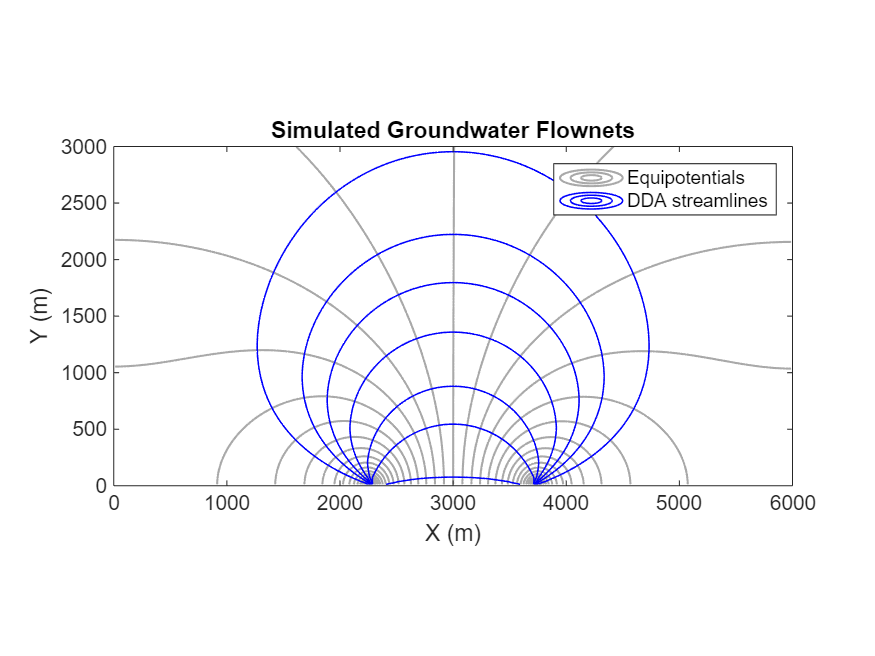

figure;                                     % creates a new figure window for plotting
opts.fill = 'off';                           % specify type of contour plot => fill between contour lines
plotContourData(G2D, h(:), opts, ...        % function that plots the head contours
    'LevelList',-275:12.5:275, ...              % add contours between -275 m and +275 m with 12.5 m interval
    'Color',rgb(Color,'darkgray'), ...          % contours color is dark gray
    'LineWidth', 1);                            % width of the contour lines

%--- Draw iso-contours of the residence time with blue color 
hold on;
[M,~] = plotContourData(G2D,rt/day,opts,...
    'LevelList',[2e+3 4e+3 8e+3 2e+4 4e+4 7e+4 1.5e+5],...
    'LineStyle','-',...
    'LineWidth',0.75,...
    'LineColor','blue');

%--- Plot customization
axis tight equal;                           % it data to axes limits + maintain aspect ratio
axis([0,6000,0,3000]);
xlabel('X (m)'); ylabel('Y (m)');           % plot X, Y axes labels
title('Simulated Groundwater Flownets');    % plot title 
legend('Equipotentials', 'DDA streamlines');
hold off; 

As expected, the flow pattern is perfectly symmetrical along the median y-axis of the rectangular domain, and the contour lines are orthogonal to the no-flow boundaries and equipotential lines, consistent with classical groundwater flownet theory. 

## Three-way Comparison using an Analytical Solution and another Numerical Solution

In this section, we conduct a three-way comparison study. The streamlines computed using the DDA will be compared to those obtained from another numerical method and then to an available analytical solution. 

figure;                                     % creates a new figure window for plotting
opts.fill = 'off';                          % specify type of contour plot => fill between contour lines

%--- Draw iso-contours of the residence time with blue color 
[M,~] = plotContourData(G2D,rt/day,opts,...
    'LevelList',[2e+3 4e+3 8e+3 2e+4 4e+4 7e+4 1.5e+5],...
    'LineStyle','-',...
    'LineWidth',0.75,...
    'LineColor','blue');

%--- Draw streamlines at the same positions using Matlab ode solvers
contourData = extractContourData(M);             % extract contour data from M matrix
Ypos = zeros(size(contourData));                 % initialize Y positions of particles       
for i = 1:length(Ypos)                           % find Y positions by intersecting residence 
   B = findIntersectionX(contourData, i, 3000);  % time contours with vertical line at Y = 3000 
   Ypos(1,i) = B(1,2);
end
clear B;

hold on;

### Comparison against an analytical solution

When examining groundwater flow in homogeneous and isotropic confined aquifers, Bear [1] and Strack [3] utilized complex potential theory to analytically derive expressions for the discharge potential, $\Phi$, and stream function, $\Psi$, components assuming Dupuit-Forchheimer conditions. The complex potential is defined as follows:


$$\Omega(z) = \Phi(z) + i \Psi(z)$$


where $z=x+iy$ is the coordinate in the complex plane. 

In the recirculation zone created by a pair of injection and extraction wells in the absence of regional flow, these functions are expressed as follows: 


$$\Phi(x,y) = \frac{Q}{4\pi} \ln [\frac{(x-d)^2+y^2}{(x+d)^2+y^2}]$$



$$\Psi(x,y) = \frac{Q}{2\pi}[\arctan(\frac{y}{x-d})-\arctan (\frac{y}{x+d})]$$


where $d$is the half-distance between the wells.

The equipotential lines are concentric circles centered around the injection and production wells. Their analytical expressions, as derived by Strack [3], are given by:

$[x+d\coth(\frac{2\pi\Phi}{Q})]^2 + y^2 = \frac{d^2}{\sinh^2(\frac{2\pi\Phi}{Q})}$   if  $\Phi \ne 0$

$x=0$                                                  if $\Phi = 0$

The streamlines also have circular shapes, with their centers located along the median vertical axis between the well pair. They are analytically expressed as follows: 

$x^2 + [y-d\cot(\frac{2\pi\Psi}{Q})]^2 = \frac{d^2}{sin^2(\frac{2\pi\Psi}{Q})}$   if $\Psi \ne 0, \pm\frac{Q}{2}$ 

$y=0$                                             if $\Psi = 0, \pm\frac{Q}{2}$

It is straightforward to show that the coordinates of the streamline, $\Psi$, center are $[0,d\cot(2\pi\Psi/Q)]$and its radius is $d/|\sin(2\pi\Psi/Q)|$. The height of the streamline arc is given by $h_s = d\tan(\frac{\pi}{2}-\frac{\pi|\psi|}{Q})$[2].

Now, let's calculate the $\Psi$ levels of the numerically computed streamlines based on their prescribed heights: 

d   = G2D.coord(wells_pos(2),1)-G2D.coord(wells_pos(1),1); d = d/2;
psi = Q*((pi/2)-atan(Ypos/d))/pi;

Next, we plot a few points for the corresponding circles of each streamline. 

rc = d./abs(sin(2*pi*psi/Q));
yc = d*cot(2*pi*psi/Q);
xp = []; yp = [];
for i=1:numel(rc)
    xp = [xp rc(i)*cos(-pi:pi/21:pi)+6000/2]; 
    yp = [yp rc(i)*sin(-pi:pi/21:pi)+yc(i)]; 
end    
plot(xp, yp, 'ko', 'MarkerSize',4);

### Comparison against another numerical solution

In this section, we will use MATLAB's built-in `streamline` function to compute similar streamlines. This function is called directly from the `plotStreamlines` command in this toolbox. Internally, the `streamline` function performs numerical integration to trace the streamlines by solving the system of ordinary differential equations that describe particle motion in the specific discharge field. MATLAB employs a variant of Runge-Kutta methods to solve these ODEs, which are commonly used for numerical integration, though the process is abstracted from the user. The solver automatically adjusts the step size to maintain accuracy while tracing the path. As a result, this approach falls into the category of numerically computed streamlines, in contrast to those derived analytically using Pollock's method.

To be sure we are comparing the same streamlines, we first extract all intersection points between the streamlines simulated with the DDA. Nest, we trace forward and backward particle paths from these positions. 

hold on;
% now plot numerically computed streamlines using Matlab integration
gs = [G2D.hx, G2D.hy];                     % uniform grid sizes along X & Y
sx = 3000*ones(1,length(Ypos));            % streamlines starting x positions
hp = plotStreamline(V,gs,[sx;Ypos],true);  % plot streamlines in forward direction ...
set(hp,'Color','r','LineWidth',0.8);       %    with blue color 
hi = plotStreamline(V,gs,[sx;Ypos],false); % plot streamlines in backward direction ...
set(hi,'Color','r','LineWidth',0.8);       %    with red color

Finally we customize the final plot.

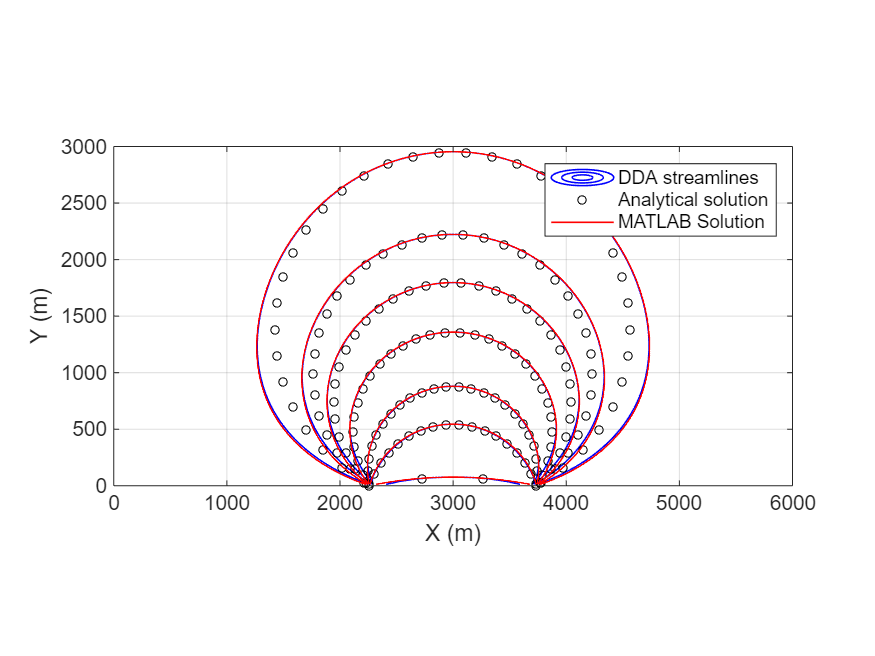

%--- Plot customization
axis tight equal;                           % it data to axes limits + maintain aspect ratio
axis([0,6000,0,3000]);
xlabel('X (m)'); ylabel('Y (m)');           % plot X, Y axes labels
legend('DDA streamlines', 'Analytical solution', 'MATLAB Solution');
box on, grid on,
hold off; 

The two numerical solutions are in perfect agreement, except for small discrepancies near the wells. Nonetheless, all streamlines correctly diverge from the injection well and converge toward the pumping well, as dictated by the physics of groundwater flow. These results demonstrate that the implementation of the DDA is both correct and accurate. The DDA offers a potential improvement over particle tracking as an alternative method.

As shown in the previous figure, the agreement between the numerically computed streamlines (plotted as solid lines) and the analytically calculated streamlines (represented by circles) is quite good. However, the quality of this agreement diminishes for the longest streamlines connecting the wells on both sides.

This discrepancy arises from boundary condition artifacts, as these streamlines approach the closed domain boundaries. In numerical simulations, particularly those involving confined aquifers, the finite boundaries of the model can influence the flow patterns, leading to deviations from expected behaviors. Unlike the analytical solution, which assumes an infinite domain, numerical methods must account for these boundaries, potentially resulting in distortions in the representation of the flow field. As streamlines near the domain edges, they may become influenced by the artificial constraints imposed by the model boundaries, causing them to diverge from the analytically derived results.

It’s important to highlight that this disagreement does not indicate a lack of accuracy in the DDA. In fact, the DDA results closely align with those obtained from another numerical simulation method, suggesting that the DDA is robust and reliable in modeling groundwater flow. The observed discrepancies serve as a reminder of the limitations inherent in numerical modeling, particularly when dealing with boundary effects.

## References

[1] Bear, J. (1979). *Hydraulics of Groundwater*. McGraw-Hill, New York. 

[2] Luo, J., and P.K. Kitanidis (2004). Fluid residence times within a recirculation zone created by an extraction-injection well pair. *J. Hydrology*, 295, 149-162. 

[3] Strack, O.D.L. (1989). *Groundwater Mechanics*, Prentice-Hall, Englewood Cliffs, NJ. 

Author: M.A. Sbai, Ph.D.

Copyright (C) 2024 Mohammed Adil Sbai

This program is free software: you can redistribute it and/or modify it under the terms of the GNU General Public License as published by the Free Software Foundation, either version 3 of the License, or (at your option) any later version.

This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. See the GNU General Public License for more details.

You should have received a copy of the GNU General Public License along with this program. If not, see <http://www.gnu.org/licenses/>.